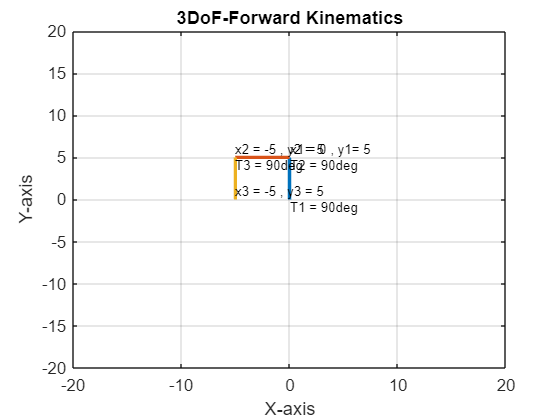

% Forward Kinematics of 3DOF robotics arm 
close all
clear all
clc

%% input values %%
l1 = 5;   % length of link-1 = l1;
l2 = 5;   % length of link-2 = l2;
l3 = 5;
theta1 = linspace(0, 90, 2);  % angle at joint-1
theta2 = linspace(0, 90, 2);  % angle at joint-2
theta3= linspace(0, 90, 2); % angle at joint-3
%% for loop iteration %%
count = 1; % counter
for i = 1:length(theta1)
    THETA1 = theta1(i);
    for j = 1:length(theta2)
        THETA2 = theta2(j);
        for k = 1:length(theta3)
            THETA3 = theta3(k);
        
        % coordinates of world frame %
        x0 = 0;
        y0 = 0;
        % another end of link-1 %
        x1 = l1*cosd(THETA1);
        y1 = l1*sind(THETA1);
        % end-effector %
        x2 = x1 + l2*cosd(THETA1+THETA2);
        y2 = y1 + l2*sind(THETA1+THETA2);
        
        x3 = x2 + l3*cosd(THETA1+THETA2+THETA3);
        y3 = y2 + l3*sind(THETA1+THETA2+THETA3);
        
        txt1 = ['T1 = ', num2str(THETA1), 'deg'];
        txt2 = ['T2 = ', num2str(THETA2), 'deg'];
        txt3 = ['T3 = ', num2str(THETA3), 'deg'];
        txtmid1 = ['x1 = ' , num2str(x1),' , ','y1= ', num2str(y1)];
        txtmid2 = ['x2 = ', num2str(x2),' , ','y2 = ', num2str(y2)];
        txtend = ['x3 = ', num2str(x3),' , ','y3 = ', num2str(y2)];
     
        %plotting
        plot([x0 x1],[y0 y1],[x1 x2],[y1 y2],[x2 x3],[y2 y3],'LineWidth',2);
        grid on
        xlabel('X-axis')
        ylabel('Y-axis')
        title('3DoF-Forward Kinematics')
        text(x0,y0,txt1,'FontSize',8,'VerticalAlignment','top')
        text(x1,y1,txt2,'FontSize',8,'VerticalAlignment','top')
        text(x2,y2,txt3,'FontSize',8,'VerticalAlignment','top')
        text(x1,y1,txtmid1,'FontSize',8,'HorizontalAlignment','left','VerticalAlignment','bottom')
        text(x2,y2,txtmid2,'FontSize',8,'HorizontalAlignment','left','VerticalAlignment','bottom')
        text(x3,y3,txtend,'FontSize',8,'HorizontalAlignment','left','VerticalAlignment','bottom')
        axis([-20 20 -20 20])
        pause(1);
        count = count + 1;
    end
end
end